# 全交换面积calc  1.1ver

%%
clear,clc
%参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.5;%黑度
rho_r = 0.5;%反射率
epsilon_w = 0.85;
rho_w = 0.15;
epsilon_s = 0.75;
rho_s = 0.25;

%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    Xrs = Xrp * 1/kr * Xp2s * ks;
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;
    % Xrr = 1 - Xrw - Xrs;
    % Xrs = 1 - Xrw - Xrr;
    

    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
RS = SR

RS =     3.7234    5.4922    4.3881    3.5848    3.5855    2.7455    1.8360    1.3795    1.3795    1.3795    1.5958


WS = SW

WS =    18.1433   12.0522   13.2919   14.2017   14.2006   15.1575   14.6637   16.7387   16.7387   16.7387   21.9358


RW = WR

RW =     8.5920   12.6123   10.1661    8.3330    8.3345    6.4046    4.3126    3.2862    3.2862    3.2862    3.7696


SR

SR =     3.7234    5.4922    4.3881    3.5848    3.5855    2.7455    1.8360    1.3795    1.3795    1.3795    1.5958


SW

SW =    18.1433   12.0522   13.2919   14.2017   14.2006   15.1575   14.6637   16.7387   16.7387   16.7387   21.9358


WR

WR =     8.5920   12.6123   10.1661    8.3330    8.3345    6.4046    4.3126    3.2862    3.2862    3.2862    3.7696


# 三元法calc   ver1.1

%初(xia)始(gei)化温度
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));


Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.3;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
hw = 10;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
timeStep = 1000;%时间步长节点数
Ts_2 = 0;%初始化，进循环用
phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),timeStep*length(cellZoneInfo));

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Tw = Tw_init(i);
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    %能量平衡解Tr
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)
        Ts_1 = Ts_2;
        syms Tr;
        f1 = sigma*RW(i)*(Tr^4 - Tw^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
        Tr = solve(f1,Tr);
        Tr = vpa(Tr);
        Tr= Tr(imag(Tr) == 0 & real(Tr) > 0)
    %能量平衡解Tw   
        syms Tw;
        f2 = sigma*SW(i)*(Ts_1^4 - Tw^4) + sigma*RW(i)*(Tr^4 - Tw^4) == Fw*(Tw - Temp_out)/(1/hw+Thw/lambda_w);
        Tw = solve(f2,Tw);
        Tw = vpa(Tw);
        Tw= Tw(imag(Tw) == 0 & real(Tw) > 0)
        
        qcon = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw^4))/Fs%钢坯表面热流密度
    %差分求物料温度    
        T = Temp_inlet(:,i);
        delta_t = Time_zone / timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),timeStep);
        for j = 1:timeStep
            T = TDMA(qcon,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/timeStep%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
    end
    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*timeStep:i*timeStep) = Temp_zone;%K

end

$$Tr = 1221.4743139382485725779771255195$$

$$Tw = 915.39472022331568860499079008829$$

$$qcon = 35611.755616611193381049240139549$$

Ts_2 = 400.2879

$$Tr = 1203.5138460797292051728547244613$$

$$Tw = 907.61534522023262088334082510057$$

$$qcon = 33129.328466806734238626999176325$$

Ts_2 = 393.6062

$$Tr = 1201.0760777634319337897880498855$$

$$Tw = 905.42283853313087239387777066427$$

$$qcon = 32883.630546924844089236267773636$$

Ts_2 = 392.9443

$$Tr = 1200.4108306184547229244313973753$$

$$Tw = 904.89079117553949773606250400853$$

$$qcon = 32812.051317807507154509130949893$$

Ts_2 = 392.7514

Temp_inlet =   303.1500  475.0175         0         0         0         0         0         0         0         0         0
  303.1500  473.1577         0         0         0         0         0         0         0         0         0
  303.1500  471.4986         0         0         0         0         0         0         0         0         0
  303.1500  470.0384         0         0         0         0         0         0         0         0         0
  303.1500  468.7757         0         0         0         0         0         0         0         0         0
  303.1500  467.7094         0         0         0         0         0         0         0         0         0
  303.1500  466.8383         0         0         0         0         0         0         0         0         0
  303.1500  466.1617         0         0         0         0         0         0         0         0         0
  303.1500  465.6788         0         0         0         0         0         0         0         

$$Tr = 1221.2095845642970388435892582383$$

$$Tw = 1031.4541052602658059928049663461$$

$$qcon = 43083.291792750217104211126778595$$

Ts_2 = 562.7352

$$Tr = 1239.197598940398986342201253913$$

$$Tw = 1054.6568067212251801288550088731$$

$$qcon = 44206.781115382600097338645230606$$

Ts_2 = 565.1294

$$Tr = 1248.7944895978423246984604438931$$

$$Tw = 1062.7549238923939757107358728419$$

$$qcon = 45627.721755721727639791118757878$$

Ts_2 = 568.1529

$$Tr = 1252.3029252193404816138289746352$$

$$Tw = 1065.8729613312638323290062689634$$

$$qcon = 46124.540382535131736397987438457$$

Ts_2 = 569.2089

$$Tr = 1253.6641305459141370907907807088$$

$$Tw = 1067.0742276253674421562593399494$$

$$qcon = 46320.048507232403169559611956201$$

Ts_2 = 569.6242

Temp_inlet =   303.1500  475.0175  658.1927         0         0         0         0         0         0         0         0
  303.1500  473.1577  655.0915         0         0         0         0         0         0         0         0
  303.1500  471.4986  652.3303         0         0         0         0         0         0         0         0
  303.1500  470.0384  649.9045         0         0         0         0         0         0         0         0
  303.1500  468.7757  647.8100         0         0         0         0         0         0         0         0
  303.1500  467.7094  646.0434         0         0         0         0         0         0         0         0
  303.1500  466.8383  644.6018         0         0         0         0         0         0         0         0
  303.1500  466.1617  643.4830         0         0         0         0         0         0         0         0
  303.1500  465.6788  642.6851         0         0         0         0         0         0         

$$Tr = 1199.5354245084323230309505398318$$

$$Tw = 984.68084846243525317316774558587$$

$$qcon = 33396.175270546173062200505745749$$

Ts_2 = 715.1589

$$Tr = 1194.8476493511561017507099101419$$

$$Tw = 1003.5492286595663327882328238564$$

$$qcon = 30146.375213340649903732481473897$$

Ts_2 = 708.7523

$$Tr = 1201.9663525585742900204463891486$$

$$Tw = 1007.4599719344624811227688140337$$

$$qcon = 31145.471020800497218296759764243$$

Ts_2 = 710.7269

$$Tr = 1203.6844291145028463598497768987$$

$$Tw = 1009.1043733620561764840422699519$$

$$qcon = 31301.57347316971474984369157438$$

Ts_2 = 711.0350

Temp_inlet =   303.1500  475.0175  658.1927  765.2701         0         0         0         0         0         0         0
  303.1500  473.1577  655.0915  762.9168         0         0         0         0         0         0         0
  303.1500  471.4986  652.3303  760.8249         0         0         0         0         0         0         0
  303.1500  470.0384  649.9045  758.9897         0         0         0         0         0         0         0
  303.1500  468.7757  647.8100  757.4072         0         0         0         0         0         0         0
  303.1500  467.7094  646.0434  756.0738         0         0         0         0         0         0         0
  303.1500  466.8383  644.6018  754.9868         0         0         0         0         0         0         0
  303.1500  466.1617  643.4830  754.1437         0         0         0         0         0         0         0
  303.1500  465.6788  642.6851  753.5427         0         0         0         0         0         

$$Tr = 1210.3675844818507184405186758767$$

$$Tw = 983.93049176731543533750604041165$$

$$qcon = 27872.460411028948365282391784265$$

Ts_2 = 809.4045

$$Tr = 1197.6076407371943324136454019249$$

$$Tw = 1003.2894417253545346653611474887$$

$$qcon = 23929.51541968503938862512115403$$

Ts_2 = 802.1128

$$Tr = 1204.6089488853537066312214744863$$

$$Tw = 1005.332015335720501680393624475$$

$$qcon = 24882.804392052049267219677106473$$

Ts_2 = 803.8770

$$Tr = 1205.5925857049400829578870676452$$

$$Tw = 1006.5155230829147041963516848288$$

$$qcon = 24930.442965334254652824659555723$$

Ts_2 = 803.9652

Temp_inlet =   303.1500  475.0175  658.1927  765.2701  843.3901         0         0         0         0         0         0
  303.1500  473.1577  655.0915  762.9168  841.3430         0         0         0         0         0         0
  303.1500  471.4986  652.3303  760.8249  839.5172         0         0         0         0         0         0
  303.1500  470.0384  649.9045  758.9897  837.9108         0         0         0         0         0         0
  303.1500  468.7757  647.8100  757.4072  836.5221         0         0         0         0         0         0
  303.1500  467.7094  646.0434  756.0738  835.3494         0         0         0         0         0         0
  303.1500  466.8383  644.6018  754.9868  834.3916         0         0         0         0         0         0
  303.1500  466.1617  643.4830  754.1437  833.6477         0         0         0         0         0         0
  303.1500  465.6788  642.6851  753.5427  833.1169         0         0         0         0         

$$Tr = 1225.8653234391403300322748813295$$

$$Tw = 1019.4494240608499870063760108723$$

$$qcon = 27103.884019518258113949380080744$$

Ts_2 = 886.0489

$$Tr = 1219.6855447577826297750370750098$$

$$Tw = 1043.9833970828721566706685179536$$

$$qcon = 23440.35058576889439975673396676$$

Ts_2 = 879.3538

$$Tr = 1229.1945525784018153752352978809$$

$$Tw = 1047.0760956377318293677821080823$$

$$qcon = 24759.174856764390596519438491522$$

Ts_2 = 881.7651

$$Tr = 1230.7888250245024579210069249716$$

$$Tw = 1048.9204179320573914506897673338$$

$$qcon = 24837.079878831065516871855361057$$

Ts_2 = 881.9075

Temp_inlet =   303.1500  475.0175  658.1927  765.2701  843.3901  919.9964         0         0         0         0         0
  303.1500  473.1577  655.0915  762.9168  841.3430  917.8415         0         0         0         0         0
  303.1500  471.4986  652.3303  760.8249  839.5172  915.9127         0         0         0         0         0
  303.1500  470.0384  649.9045  758.9897  837.9108  914.2102         0         0         0         0         0
  303.1500  468.7757  647.8100  757.4072  836.5221  912.7343         0         0         0         0         0
  303.1500  467.7094  646.0434  756.0738  835.3494  911.4851         0         0         0         0         0
  303.1500  466.8383  644.6018  754.9868  834.3916  910.4628         0         0         0         0         0
  303.1500  466.1617  643.4830  754.1437  833.6477  909.6676         0         0         0         0         0
  303.1500  465.6788  642.6851  753.5427  833.1169  909.0995         0         0         0         

$$Tr = 1238.53590850481665389617666641$$

$$Tw = 1025.2316704429715119046394932985$$

$$qcon = 20960.765480810675589858457057646$$

Ts_2 = 950.7313

$$Tr = 1226.3311990586042314712135096322$$

$$Tw = 1052.2684934674783898046524611878$$

$$qcon = 17216.950160403927185931769680345$$

Ts_2 = 943.9125

$$Tr = 1236.7571726454990343175861611882$$

$$Tw = 1053.7243193712039616678320429253$$

$$qcon = 18456.741667024728915425628467356$$

Ts_2 = 946.1708

$$Tr = 1237.6873805139191179070531979466$$

$$Tw = 1055.3041770852140573470587098586$$

$$qcon = 18448.565575133694299502993800359$$

Ts_2 = 946.1559

Temp_inlet =   303.1500  475.0175  658.1927  765.2701  843.3901  919.9964  974.1416         0         0         0         0
  303.1500  473.1577  655.0915  762.9168  841.3430  917.8415  972.5537         0         0         0         0
  303.1500  471.4986  652.3303  760.8249  839.5172  915.9127  971.1324         0         0         0         0
  303.1500  470.0384  649.9045  758.9897  837.9108  914.2102  969.8781         0         0         0         0
  303.1500  468.7757  647.8100  757.4072  836.5221  912.7343  968.7908         0         0         0         0
  303.1500  467.7094  646.0434  756.0738  835.3494  911.4851  967.8705         0         0         0         0
  303.1500  466.8383  644.6018  754.9868  834.3916  910.4628  967.1175         0         0         0         0
  303.1500  466.1617  643.4830  754.1437  833.6477  909.6676  966.5317         0         0         0         0
  303.1500  465.6788  642.6851  753.5427  833.1169  909.0995  966.1132         0         0         

$$Tr = 1254.188014571195838986606991894$$

$$Tw = 1037.6266376290375064323272724601$$

$$qcon = 14087.38123609829315410624303344$$

Ts_2 = 992.5027

$$Tr = 1236.314738439606044241233418867$$

$$Tw = 1059.0040110737326168011685647746$$

$$qcon = 11384.003060185043015689869635946$$

Ts_2 = 987.9284

$$Tr = 1244.6700962905859589927030260759$$

$$Tw = 1059.1652627261110804614495110129$$

$$qcon = 12097.821429976617880353129986057$$

Ts_2 = 989.1364

$$Tr = 1244.9204038865740205372520007166$$

$$Tw = 1060.0100742919154217505382144352$$

$$qcon = 12073.229731467275651211959992646$$

Ts_2 = 989.0948

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6582    0.7653    0.8434    0.9200    0.9741    1.0059         0         0         0
    0.3031    0.4732    0.6551    0.7629    0.8413    0.9178    0.9726    1.0048         0         0         0
    0.3031    0.4715    0.6523    0.7608    0.8395    0.9159    0.9711    1.0039         0         0         0
    0.3031    0.4700    0.6499    0.7590    0.8379    0.9142    0.9699    1.0031         0         0         0
    0.3031    0.4688    0.6478    0.7574    0.8365    0.9127    0.9688    1.0024         0         0         0
    0.3031    0.4677    0.6460    0.7561    0.8353    0.9115    0.9679    1.0018         0         0         0
    0.3031    0.4668    0.6446    0.7550    0.8344    0.9105    0.9671    1.0013         0         0         0
    0.3031    0.4662    0.6435    0.7541    0.8336    0.9097    0.9665    1.0009         0         0         0
    0.3031    0.4657    0.6427    0.7535    0.8331    0.9091    0.9661    1.0006        

$$Tr = 1252.4511553613090259485045476275$$

$$Tw = 1042.7920616195787606369306335297$$

$$qcon = 9901.8493113533600767836789390464$$

Ts_2 = 1.0203e+03

$$Tr = 1224.6748312012994648958034464428$$

$$Tw = 1058.0486707536824179961158679463$$

$$qcon = 7529.2543616008636842959879904639$$

Ts_2 = 1.0160e+03

$$Tr = 1230.678607036906574322836165582$$

$$Tw = 1056.3817368723029434855081904511$$

$$qcon = 7968.3900213873680661466546950277$$

Ts_2 = 1.0168e+03

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6582    0.7653    0.8434    0.9200    0.9741    1.0059    1.0289         0         0
    0.3031    0.4732    0.6551    0.7629    0.8413    0.9178    0.9726    1.0048    1.0282         0         0
    0.3031    0.4715    0.6523    0.7608    0.8395    0.9159    0.9711    1.0039    1.0276         0         0
    0.3031    0.4700    0.6499    0.7590    0.8379    0.9142    0.9699    1.0031    1.0270         0         0
    0.3031    0.4688    0.6478    0.7574    0.8365    0.9127    0.9688    1.0024    1.0266         0         0
    0.3031    0.4677    0.6460    0.7561    0.8353    0.9115    0.9679    1.0018    1.0262         0         0
    0.3031    0.4668    0.6446    0.7550    0.8344    0.9105    0.9671    1.0013    1.0259         0         0
    0.3031    0.4662    0.6435    0.7541    0.8336    0.9097    0.9665    1.0009    1.0256         0         0
    0.3031    0.4657    0.6427    0.7535    0.8331    0.9091    0.9661    1.0006    1.02

$$Tr = 1257.1678213823647143513855219503$$

$$Tw = 1063.9464776492406123535049701642$$

$$qcon = 9364.1470965596556145928295510509$$

Ts_2 = 1.0435e+03

$$Tr = 1227.9634569566938501487635352155$$

$$Tw = 1076.3168738940224019405657587105$$

$$qcon = 6970.1693393802498475611900072543$$

Ts_2 = 1.0392e+03

$$Tr = 1232.9161593161523763619962439683$$

$$Tw = 1074.246030367926673704426963419$$

$$qcon = 7366.996329214782688196084271062$$

Ts_2 = 1.0399e+03

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6582    0.7653    0.8434    0.9200    0.9741    1.0059    1.0289    1.0511         0
    0.3031    0.4732    0.6551    0.7629    0.8413    0.9178    0.9726    1.0048    1.0282    1.0505         0
    0.3031    0.4715    0.6523    0.7608    0.8395    0.9159    0.9711    1.0039    1.0276    1.0499         0
    0.3031    0.4700    0.6499    0.7590    0.8379    0.9142    0.9699    1.0031    1.0270    1.0494         0
    0.3031    0.4688    0.6478    0.7574    0.8365    0.9127    0.9688    1.0024    1.0266    1.0490         0
    0.3031    0.4677    0.6460    0.7561    0.8353    0.9115    0.9679    1.0018    1.0262    1.0486         0
    0.3031    0.4668    0.6446    0.7550    0.8344    0.9105    0.9671    1.0013    1.0259    1.0483         0
    0.3031    0.4662    0.6435    0.7541    0.8336    0.9097    0.9665    1.0009    1.0256    1.0481         0
    0.3031    0.4657    0.6427    0.7535    0.8331    0.9091    0.9661    1.0006    1.02

$$Tr = 1266.0416323722923828725261939692$$

$$Tw = 1083.1830452895968757499340034$$

$$qcon = 9143.6279974669927597048833825588$$

Ts_2 = 1.0655e+03

$$Tr = 1240.9312971526375082835644924058$$

$$Tw = 1096.1553838434072885269818001997$$

$$qcon = 6914.5863458641025382929496313589$$

Ts_2 = 1.0615e+03

$$Tr = 1246.3298407490803680316234662677$$

$$Tw = 1094.367453192627385995706489836$$

$$qcon = 7342.2791564346289648992699281073$$

Ts_2 = 1.0623e+03

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6582    0.7653    0.8434    0.9200    0.9741    1.0059    1.0289    1.0511    1.0734
    0.3031    0.4732    0.6551    0.7629    0.8413    0.9178    0.9726    1.0048    1.0282    1.0505    1.0728
    0.3031    0.4715    0.6523    0.7608    0.8395    0.9159    0.9711    1.0039    1.0276    1.0499    1.0722
    0.3031    0.4700    0.6499    0.7590    0.8379    0.9142    0.9699    1.0031    1.0270    1.0494    1.0718
    0.3031    0.4688    0.6478    0.7574    0.8365    0.9127    0.9688    1.0024    1.0266    1.0490    1.0713
    0.3031    0.4677    0.6460    0.7561    0.8353    0.9115    0.9679    1.0018    1.0262    1.0486    1.0710
    0.3031    0.4668    0.6446    0.7550    0.8344    0.9105    0.9671    1.0013    1.0259    1.0483    1.0707
    0.3031    0.4662    0.6435    0.7541    0.8336    0.9097    0.9665    1.0009    1.0256    1.0481    1.0705
    0.3031    0.4657    0.6427    0.7535    0.8331    0.9091    0.9661    1.0006    1.02

$$Tr = 1295.8006367660380290805075630809$$

$$Tw = 1103.3493940426292404011859808$$

$$qcon = 11932.884366980924079058901562138$$

Ts_2 = 1.0982e+03

$$Tr = 1283.6070168821332523423236097458$$

$$Tw = 1128.3278030611148580121930458493$$

$$qcon = 9581.31911860489542611755860578$$

Ts_2 = 1.0929e+03

$$Tr = 1294.0282452335775955400597159874$$

$$Tw = 1126.4644692853081880924337635762$$

$$qcon = 10537.620283756151848851643131715$$

Ts_2 = 1.0951e+03

$$Tr = 1293.5500234161242694648577163033$$

$$Tw = 1128.0353277580552534178182360744$$

$$qcon = 10410.44143089206750286833848708$$

Ts_2 = 1.0948e+03

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6582    0.7653    0.8434    0.9200    0.9741    1.0059    1.0289    1.0511    1.0734    1.1152
    0.3031    0.4732    0.6551    0.7629    0.8413    0.9178    0.9726    1.0048    1.0282    1.0505    1.0728    1.1143
    0.3031    0.4715    0.6523    0.7608    0.8395    0.9159    0.9711    1.0039    1.0276    1.0499    1.0722    1.1136
    0.3031    0.4700    0.6499    0.7590    0.8379    0.9142    0.9699    1.0031    1.0270    1.0494    1.0718    1.1129
    0.3031    0.4688    0.6478    0.7574    0.8365    0.9127    0.9688    1.0024    1.0266    1.0490    1.0713    1.1123
    0.3031    0.4677    0.6460    0.7561    0.8353    0.9115    0.9679    1.0018    1.0262    1.0486    1.0710    1.1118
    0.3031    0.4668    0.6446    0.7550    0.8344    0.9105    0.9671    1.0013    1.0259    1.0483    1.0707    1.1114
    0.3031    0.4662    0.6435    0.7541    0.8336    0.9097    0.9665    1.0009    1.0256    1.0481    1.0705    1.1111
    0.30

Tw_zone - 273.15%各段温度

ans =   631.7408  793.9242  735.9544  733.3655  775.7704  782.1542  786.8601  783.2317  801.0960  821.2175  854.8853


Tr_zone - 273.15

ans = 1.0e+03 *

    0.9273    0.9805    0.9305    0.9324    0.9576    0.9645    0.9718    0.9575    0.9598    0.9732    1.0204


Ts_zone - 273.15

ans =   119.6014  296.4742  437.8850  530.8152  608.7575  673.0059  715.9448  743.6303  766.7501  789.1098  821.6284


Temp_zone(1,timeStep) - 273.15 %物料出炉温度

ans = 842.0538

Temp_total = Temp_total -273.15%钢温温度场

Temp_total =    33.4032   32.5961   33.9494   33.9633   34.6426   34.8864   35.3260   35.6175   35.9602   36.2478   36.5435   36.8151   37.0830   37.3378   37.5865   37.8266   38.0608   38.2887   38.5114   38.7292   38.9427   39.1522   39.3581   39.5607   39.7604   39.9574   40.1520   40.3444   40.5347   40.7232   40.9101   41.0954   41.2794   41.4621   41.6437   41.8242   42.0038   42.1825   42.3605   42.5377   42.7143   42.8903   43.0658   43.2408   43.4153   43.5895   43.7632   43.9366   44.1098   44.2826
   31.3021   31.5740   32.2573   32.6036   33.0646   33.4060   33.7711   34.0879   34.4027   34.6940   34.9773   35.2467   35.5078   35.7592   36.0034   36.2403   36.4710   36.6961   36.9161   37.1315   37.3427   37.5502   37.7542   37.9551   38.1533   38.3488   38.5421   38.7332   38.9224   39.1098   39.2957   39.4802   39.6633   39.8452   40.0260   40.2059   40.3849   40.5630   40.7404   40.9171   41.0932   41.2687   41.4438   41.6183   41.7924   41.9662   42.1396   42.3126   42.

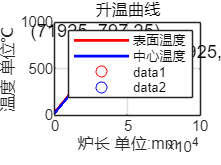






% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];
y1_total = [];
y11_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, timeStep);
    x_total = [x_total, x];
    
    % 创建当前区间的矩阵 11x800
    matrix = Temp_total(:, 1 + (i-1) * timeStep : i * timeStep);
    
    % 提取第一行和最后一行
    y1 = matrix(1, :);
    y11 = matrix(11, :);
    
    % 累积 y 坐标
    y1_total = [y1_total, y1];
    y11_total = [y11_total, y11];
    
    % 更新 x 起点
    x_start = x_end;
end

% 绘制折线图
figure;
plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); % 第一行用红色绘制
hold on;
plot(x_total, y11_total, 'b-', 'LineWidth', 1.5); % 最后一行用蓝色绘制

% 添加图例和标签
legend('表面温度', '中心温度');
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
y1_target = y1_total(idx);
y11_target = y11_total(idx);

% 在图中标注 x = 71925 时对应的 y 值
plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');

hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解全隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


